clear all

% Rotational Inertia of Ball
mass = 0.5126; % from original calculations
b = 0.1696/2; % meters
c = b;
I = 0.2*mass*(b^2 + c^2); % Rotational Inertia around semi-axis a of ellipsoid

% Torque needed to spin ball at set rpm
rpm = 500; % speed we want ball to spin
rpm = convangvel(rpm, 'rpm', 'rad/s');
t = 0.2; % contact time

T_ball = I*(rpm/t) % Newton-meters

T_ball = 0.3860


% Force required to spin ball at set rpm
r_ball = b; % meters
theta = 25; % degrees

F_ball = (T_ball/r_ball)/sind(theta) % Newtons

F_ball = 10.7710

F_ball_per_motor = F_ball/2

F_ball_per_motor = 5.3855


% Torque required by motor to achieve necessary force
r_wheel = 0.1905; % meters

T_motor = F_ball * r_wheel % Newton-meters

T_motor = 2.0519

T_per_motor = T_motor/2

T_per_motor = 1.0259


% Necessary RPM of motor for calculated torque and desired Ball RPM
rpm = 500;
r_ratio = r_ball/r_wheel

r_ratio = 0.4451

rpm_motor = rpm * r_ratio

rpm_motor = 222.5722

syms f(y) s(x) cu(x)
% Torque-Speed Chart for REV Neo 550
Stall = [0, 0.97]; % RPM-Nm
No_load = [11000, 0]; % RPM-Nm

coefficients = polyfit(No_load, Stall, 1);
m = coefficients(1);
b = coefficients(2);

f(y) = (y-b)/m; % Find RPM from Torque on chart

Neo_RPM = eval(f(T_per_motor))

Neo_RPM = -634.3131


s(x) = m*x + b; % Find Torque from RPM on c hart

Power = zeros(No_load);
for i = 1:No_load(1)
    Power(i) = i*eval(s(i)) / 9550 * 1000;
end

Stall_Current = [1.4 100];
No_load_Current = [11000 0];

coefficients = polyfit(No_load_Current, Stall_Current, 1);
m = coefficients(1);
b = coefficients(2);

cu(x) = m*x + b;

Current = zeros(No_load);
for i = 1:No_load(1)
    Current(i) = eval(cu(i));
end

V = 12;
Power_input = V * Current;

Eff = Power./Power_input;

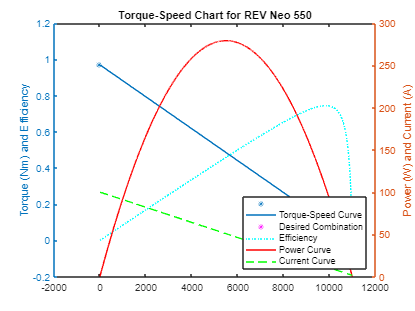

figure()
title('Torque-Speed Chart for REV Neo 550')
yyaxis left
plot(No_load, Stall, '*', DisplayName=""); hold on
line(No_load, Stall, DisplayName='Torque-Speed Curve');
plot(Neo_RPM, T_per_motor, 'm*', DisplayName='Desired Combination');
ylabel('Torque (Nm) and Efficiency')
yyaxis right
plot(Power, 'r', DisplayName='Power Curve')
plot(Current, 'g', DisplayName='Current Curve')
ylim([0,300])
ylabel('Power (W) and Current (A)')
yyaxis left
plot(Eff, 'c', DisplayName='Efficiency')
legend(Location='southeast')

% Torque-Speed Chart for 2.5in CIM motor
Stall = [0, 2.420395]; % RPM-Nm
No_load = [5310, 0]; % RPM-Nm

coefficients = polyfit(No_load, Stall, 1);
m = coefficients(1);
b = coefficients(2);

f(y) = (y-b)/m; % Find RPM from Torque on chart

CIM_RPM = eval(f(T_per_motor))

CIM_RPM = 3.0592e+03


cu(x) = m*x + b; % Find Torque from RPM on chart


Power = zeros(No_load);
for i = 1:No_load(1)
    Power(i) = i*eval(cu(i)) / 9550 * 1000;
end

Stall_Current = [2.5 131.227];
No_load_Current = [5310 0];

coefficients = polyfit(No_load_Current, Stall_Current, 1);
m = coefficients(1);
b = coefficients(2);

cu(x) = m*x + b;

Current = zeros(No_load);
for i = 1:No_load(1)
    Current(i) = eval(cu(i));
end



eval(cu(CIM_RPM))

ans = 57.0636

V = 12;
Power_input = V * Current;

Eff = Power./Power_input;

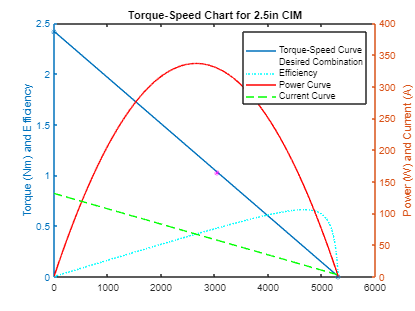

figure()
title('Torque-Speed Chart for 2.5in CIM')
yyaxis left
plot(No_load, Stall, '*', DisplayName=""); hold on
line(No_load, Stall, DisplayName='Torque-Speed Curve');
plot(CIM_RPM, T_per_motor, 'm*', DisplayName='Desired Combination');
ylabel('Torque (Nm) and Efficiency')
yyaxis right
plot(Power, 'r', DisplayName='Power Curve')
plot(Current, 'g', DisplayName='Current Curve')
ylim([0,400])
ylabel('Power (W) and Current (A)')
yyaxis left
plot(Eff, 'c', DisplayName='Efficiency')
legend(Location='northeast')